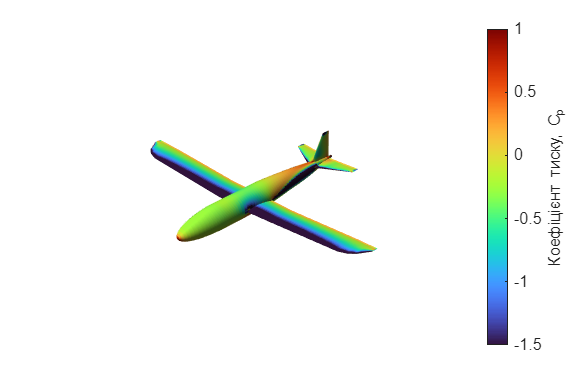

function plot_Cp(panels, Cp,mask)

    close all force; 

    valid_idx = logical(mask(:));

    valid_panels = panels(valid_idx, :, :);
    plot_data = Cp(valid_idx);

    X_draw = valid_panels(:, :, 1)'; 
    Y_draw = valid_panels(:, :, 2)'; 
    Z_draw = valid_panels(:, :, 3)'; 

    c_min = -1.5;
    c_max =  1; 

    plot_data(plot_data < c_min) = c_min;
    plot_data(plot_data > c_max) = c_max;
    
    figure('Name', 'Cp Distribution', 'Color', 'w', 'Position', [100 100 1200 800]); 

    p = patch(X_draw, Y_draw, Z_draw, plot_data');

    set(p, 'FaceColor', 'flat', 'EdgeColor', 'none', 'FaceAlpha', 1.0);    

    axis equal; 
    axis off;          
    view(135, 30);     

    camlight('headlight'); 
    lighting gouraud;      
    material dull;          


    delete(findall(gcf,'Type','light')); 

    light('Position', [-1 -1 1], 'Style', 'infinite');

    lighting gouraud;
    material dull;

    colormap(turbo); 

    clim([c_min c_max]); 

    c = colorbar;
    c.Label.String = 'Коефіцієнт тиску, C_p';
    c.Label.Interpreter = 'tex';
    c.Label.FontSize = 48;
    c.TickLabelInterpreter = 'tex';
    c.FontSize = 12;
    camproj('perspective'); 

    midX = (min(X_draw(:)) + max(X_draw(:))) / 2;
    midY = (min(Y_draw(:)) + max(Y_draw(:))) / 2;
    midZ = (min(Z_draw(:)) + max(Z_draw(:))) / 2;

    camtarget([midX, midY, midZ]);

    view(-45, 30); 

    camzoom(1.0); 
    axis vis3d tight; 
    camzoom(1.2); 


    delete(findall(gcf,'Type','light'));

    hL = camlight('left'); 
    lighting gouraud;
    material dull;
end

plot_Cp(panels, Cp ,mask);